## Naïve Bayes Analysis part 2

Analysis & Hyperparameter Search on the dataset here uses the normalised dataset with fewer features. The prior distribution is set to the training dataset's empricial distribution.

Naive Bayes classification is performed using boostrapping, which is recomended for large datasets: the training and testing times are shortest, and has acceptable type 1 error: noise in the dataset causes the algorithm to detect a difference when there is none [4].

Several metrics are calculated for the multiclass naive Bayes classifier: 

- precision, recall, accuracy[1] 

- F1 [2]. 

Training and testing of the training dataset is performed using MATlab's fitcnb and predict functionality [3]. All the kernel smoothing algorithms covered in the MATLAB documentation [3] are evaluated.

### This section clears the workspace, loads the dataset

The dataset used is the normalised dataset, using z-score normalization [6], the features previously identified as not useful are removed.

% CLear all, load the dataset
clear
clc
clf
close all
% loads the letter dataset 
% 
load letterDatasetClass.mat
letterDataset = letterDatasetNormalisedReducedFeatures;
disp(letterDataset);

  LetterDatasetClass with properties:

           datasetFilePath: "Dataset/letter-recognition.csv"
         testSetProportion: 0.2000
                randomSeed: 1
                targetName: {'TargetAscii'}
              featureNames: {1×12 cell}
          validClassValues: [26×1 table]
    datasetContentsAsTable: [20000×13 table]
                trainTable: [16000×13 table]
                 testTable: [4000×13 table]
              isNormalised: 1
          isRemovedFeature: 1



## Run Hyperparameter Search

### Using MATLAB's Default 'normal' Distribution Name

The 'normal' distribution name search is used as benchmark check for subsequent searches. 

#### Hyperparameter Search

nBayes = NBayesClass.getDefaultInstanceNoFit(letterDataset);
hyperparameters = NBayesHyperparameterClass.getDefaultTestHyperparametersInstance(nBayes);
startTime = cputime;
results = nBayes.performHyperparameterSearch(hyperparameters, "nBayesDefaultSmootherSearch.csv");

Starting Naive Bayes analysis...
Completed NBayes analysis


endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.04f", totalTime);

Total cpu time (seconds): 14.1719

#### Results

results = NBayesResults.getInstanceFromCsvResults("nBayesDefaultSmootherSearch.csv");
disp(results.resultsTable);

    distributionName    smootherType    Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ____________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'normal'}        {'unused'}      -1            2                 1               0.34

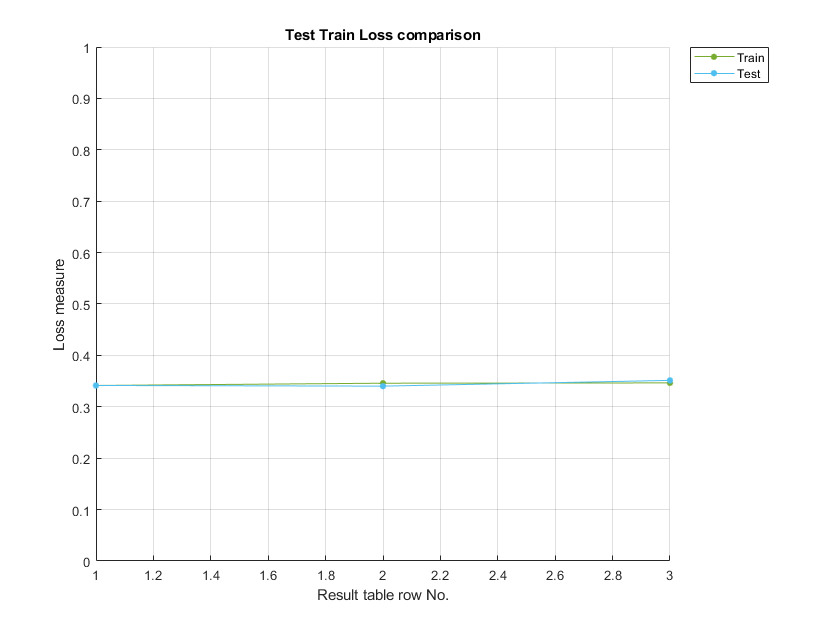

PlotUtil.plotLossTestTrainComparison(results.resultsTable, "Test Train Loss comparison");

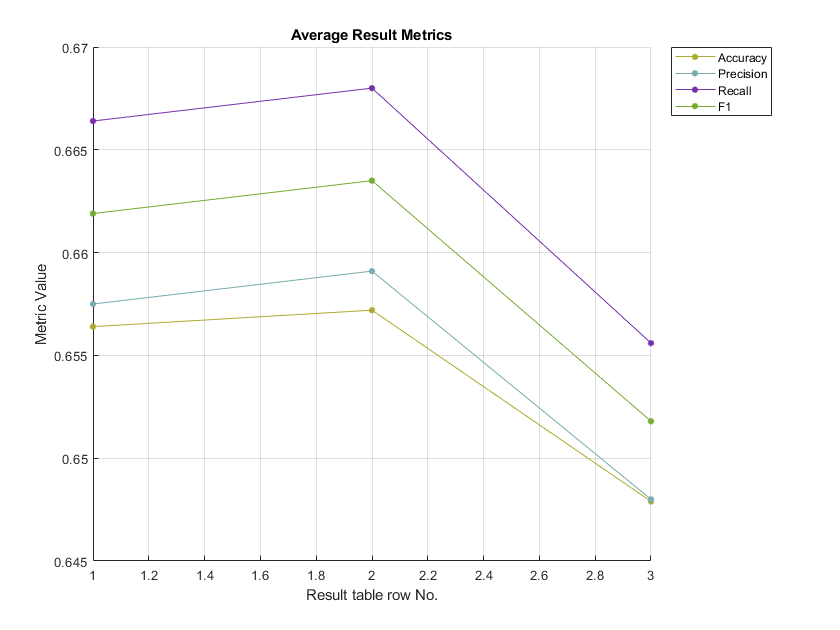

PlotUtil.plotMetrics(results.resultsTable, "Average Result Metrics");

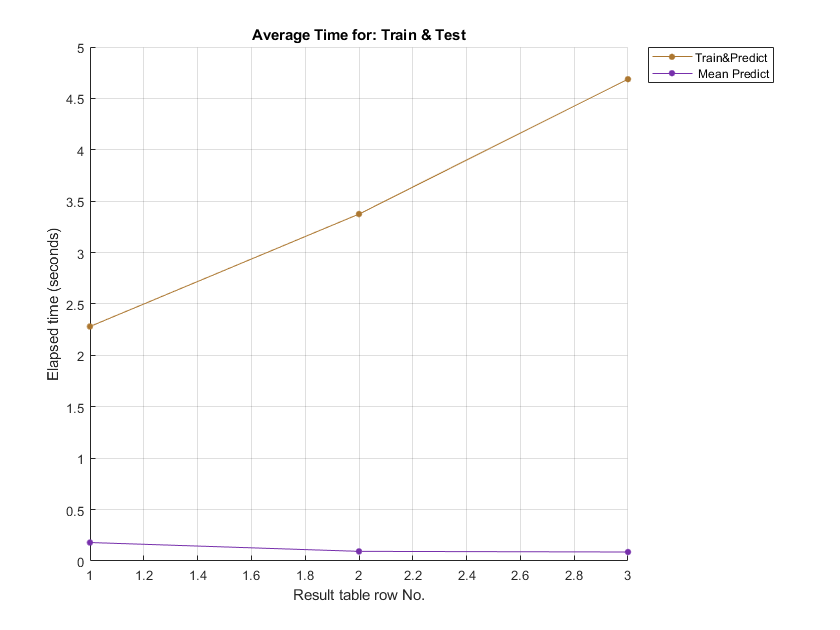

PlotUtil.plotTime(results.resultsTable, "Average Time for: Train & Test")

### Using MATLAB's Kernel Distribution Names, All Smoothers and Selected Widths

#### Triangle Smoother Type Hyperparameter Search

nBayes = NBayesClass.getDefaultInstanceNoFit(letterDataset);
hyperparameters = NBayesHyperparameterClass.getKernelTriangleSmootherHyperparametersInstance(nBayes);
startTime = cputime;
results = nBayes.performHyperparameterSearch(hyperparameters, "nBayesTriangleSmootherSearch.csv");

Starting Naive Bayes analysis...
Completed NBayes analysis


endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.04f", totalTime);

Total cpu time (seconds): 2861.7969

#### Triangle Smoother Type Results

results = NBayesResults.getInstanceFromCsvResults("nBayesTriangleSmootherSearch.csv");
disp(results.resultsTable);

    distributionName    smootherType    Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ____________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}       {'triangle'}     0.2           2                  1              0.24

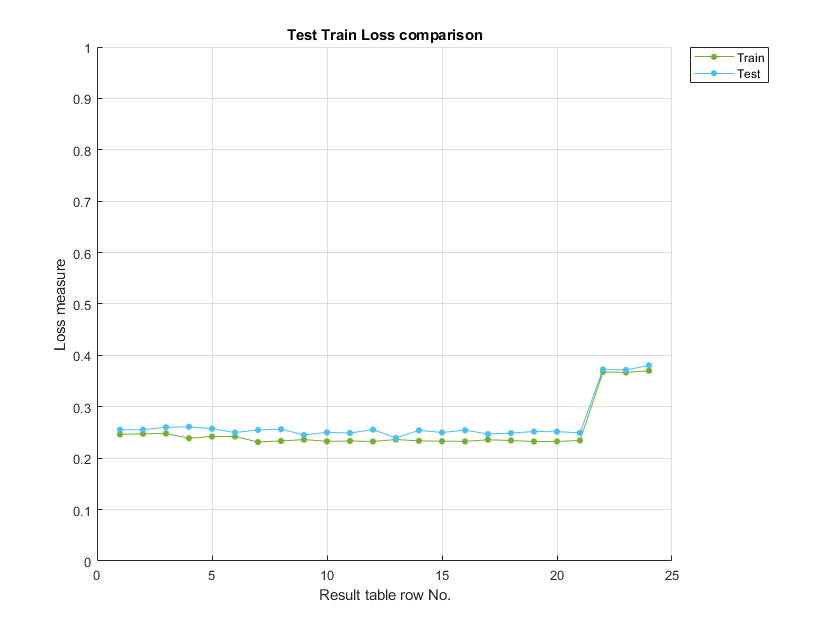

PlotUtil.plotLossTestTrainComparison(results.resultsTable, "Test Train Loss comparison");

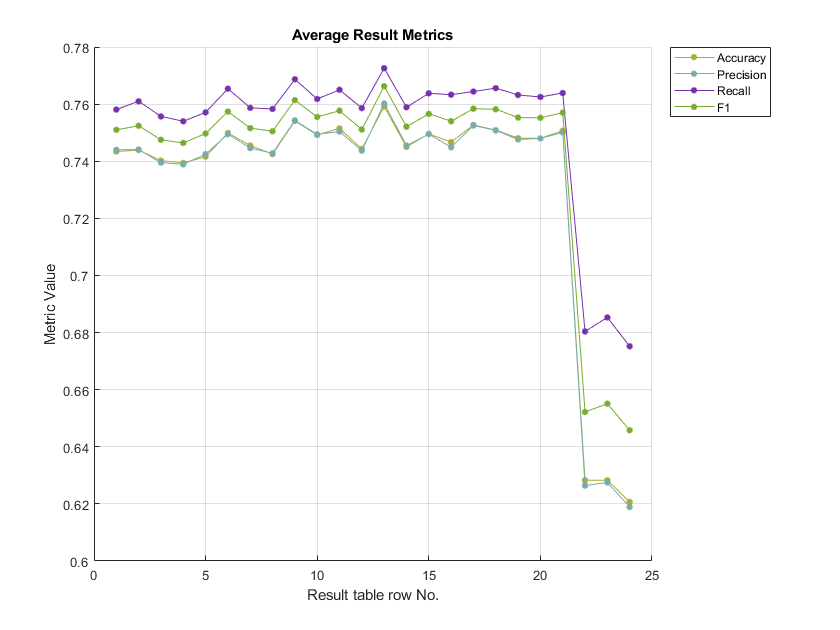

PlotUtil.plotMetrics(results.resultsTable, "Average Result Metrics");

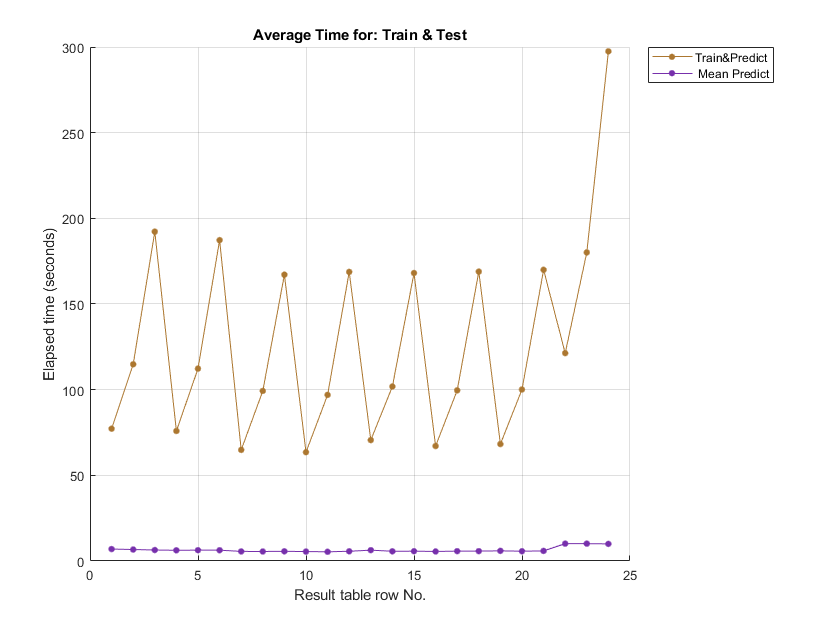

PlotUtil.plotTime(results.resultsTable, "Average Time for: Train & Test")

The rows that perform best in terms of accuracy are 1, 6, 9, 13, 18

disp(results.resultsTable([6, 9, 13, 18],:))

    distributionName    smootherType    Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ____________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}       {'triangle'}    0.18           5                  6              0.24

The quickest also happens to be the best in terms of accuracy, precision, recall and f1 score:

**2 folds, triangle kernel smoother, width 0.098351**

bestTriangle = results.resultsTable([13],:)

bestTriangle = 1×14 table
    distributionName    smootherType    Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ____________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}       {'triangle'}    0.11           2           

#### Normal Smoother Type Hyperparameter Search

nBayes = NBayesClass.getDefaultInstanceNoFit(letterDataset);
hyperparameters = NBayesHyperparameterClass.getKernalNormalSmootherHyperparametersInstance(nBayes);
startTime = cputime;
results = nBayes.performHyperparameterSearch(hyperparameters, "nBayesNormalSmootherSearch.csv");

Starting Naive Bayes analysis...
Completed NBayes analysis


endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.04f", totalTime);

Total cpu time (seconds): 6626.0400

#### Normal Smoother Type Results

results = NBayesResults.getInstanceFromCsvResults("nBayesNormalSmootherSearch.csv");
disp(results.resultsTable);

    distributionName    smootherType    Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ____________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}        {'normal'}      0.2           2                  1              0.24

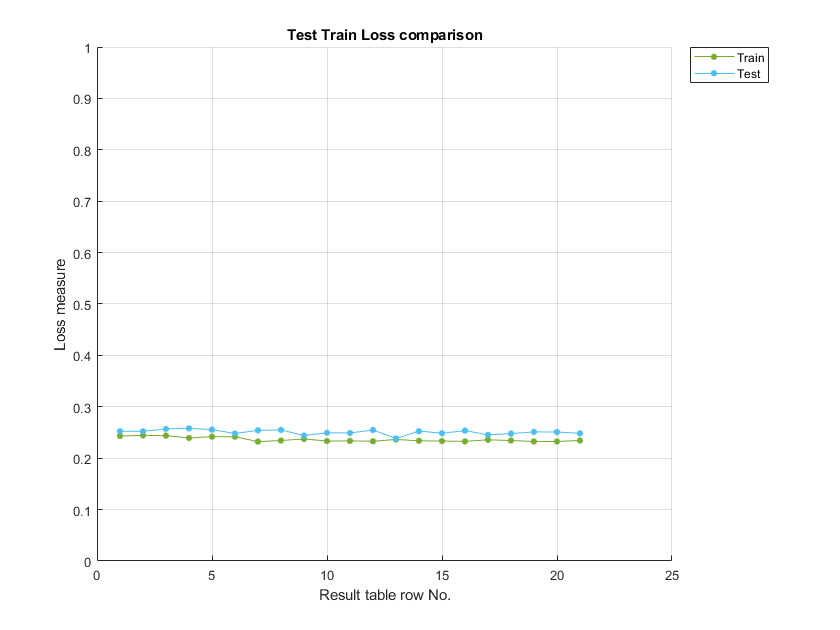

PlotUtil.plotLossTestTrainComparison(results.resultsTable, "Test Train Loss comparison");

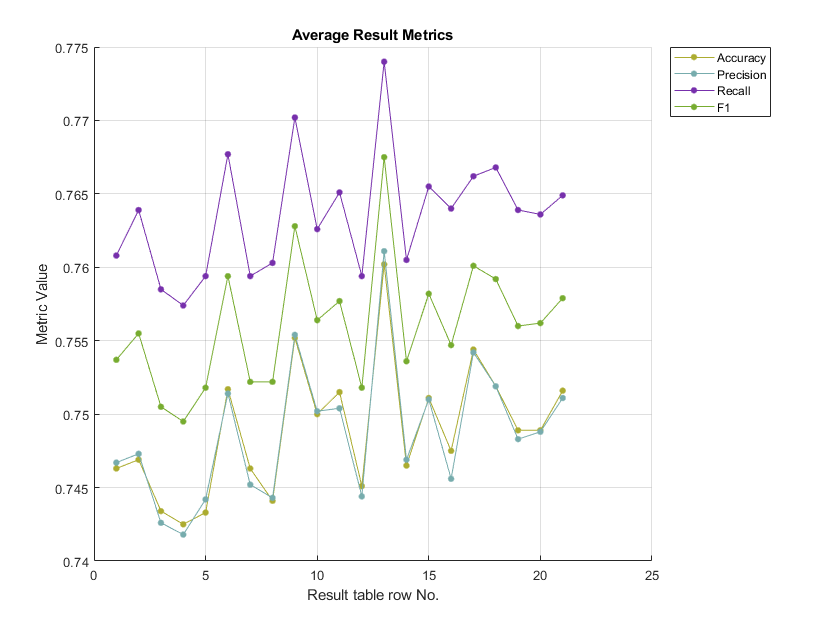

PlotUtil.plotMetrics(results.resultsTable, "Average Result Metrics");

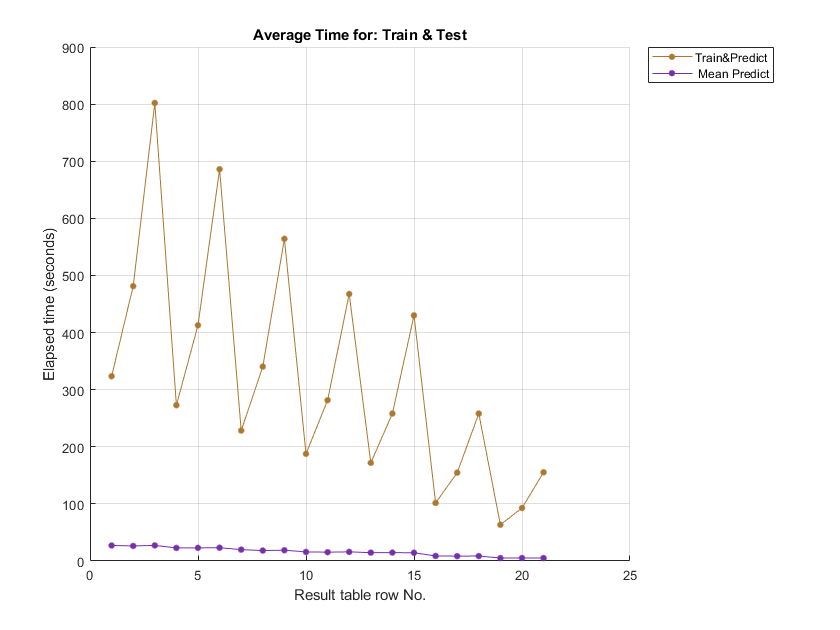

PlotUtil.plotTime(results.resultsTable, "Average Time for: Train & Test")

In terms of accuracy, row 13 is the best, the quickest times are for rows 13, 16, 19

disp(results.resultsTable([13, 16, 19],:))

    distributionName    smootherType    Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ____________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}        {'normal'}     0.11           2                 13              0.23

The best one takes longer, but only by a matter of a few minutes. The hyperparameters to use here are:

**2 folds, normal kernel smoother, width 0.11**

bestNormal = results.resultsTable([13],:)

bestNormal = 1×14 table
    distributionName    smootherType    Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ____________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}        {'normal'}     0.11           2             

#### Epanechnikov Smoother Type Hyperparameter Search

nBayes = NBayesClass.getDefaultInstanceNoFit(letterDataset);
hyperparameters = NBayesHyperparameterClass.getKernalEpanechnikovSmootherHyperparametersInstance(nBayes);
startTime = cputime;
results = nBayes.performHyperparameterSearch(hyperparameters, "nBayesEpanechikovSmootherSearch.csv");

Starting Naive Bayes analysis...
Completed NBayes analysis


endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.04f", totalTime);

Total cpu time (seconds): 2966.8200

#### Epanechnikov Smoother Type Hyperparameter Results

results = NBayesResults.getInstanceFromCsvResults("nBayesEpanechikovSmootherSearch.csv");
disp(results.resultsTable);

    distributionName      smootherType      Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ________________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}       {'epanechnikov'}     0.2           2                  1      

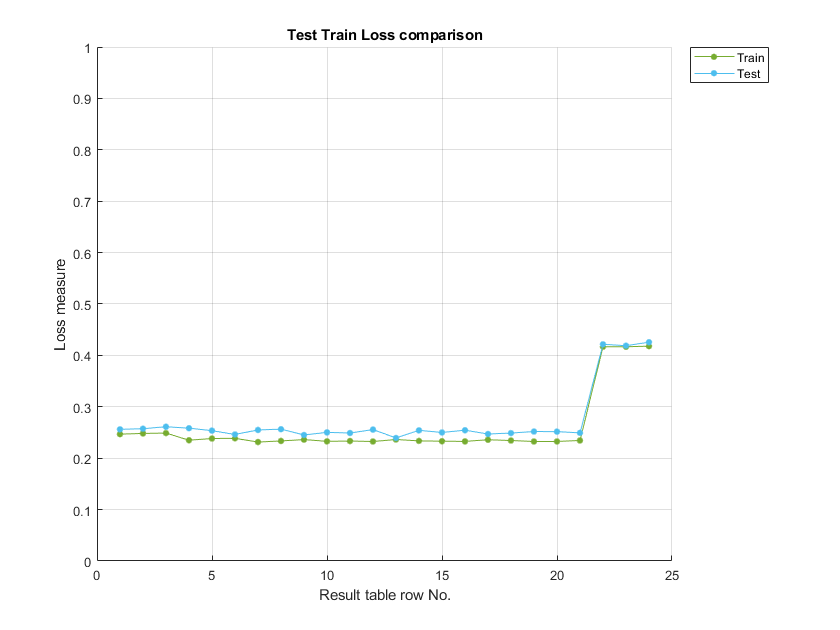

PlotUtil.plotLossTestTrainComparison(results.resultsTable, "Test Train Loss comparison");

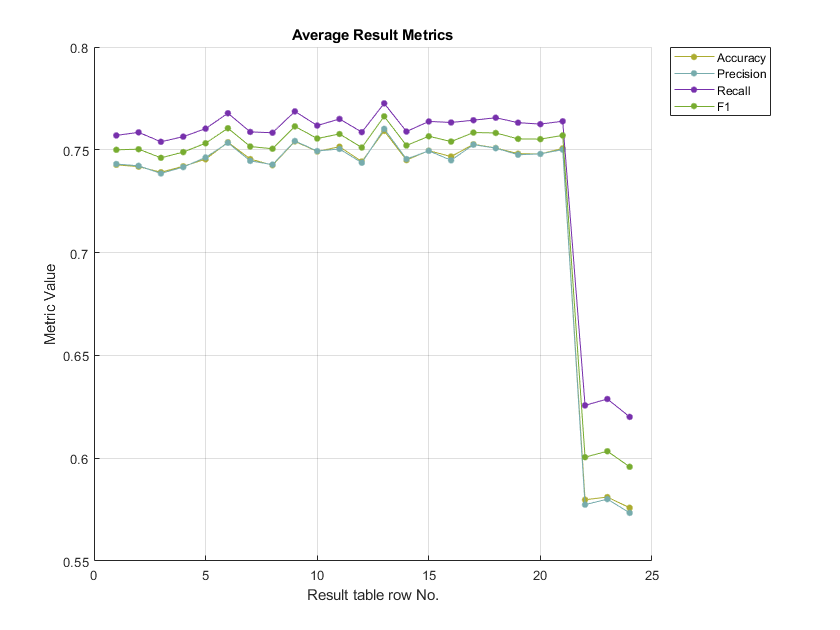

PlotUtil.plotMetrics(results.resultsTable, "Average Result Metrics");

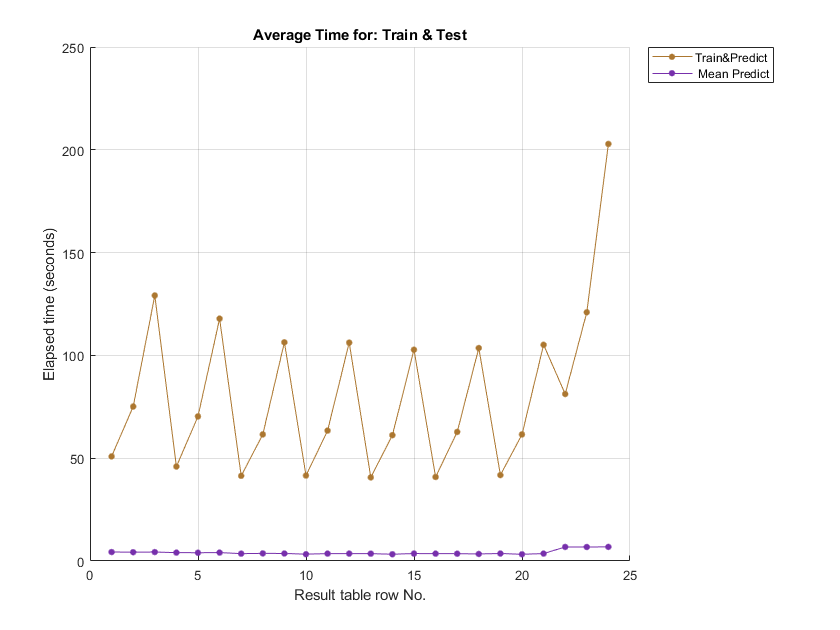

PlotUtil.plotTime(results.resultsTable, "Average Time for: Train & Test")

The rows that perform best in terms of accuracy are 1, 6, 9, 13, 18

disp(results.resultsTable([6, 9, 13, 18],:))

    distributionName      smootherType      Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ________________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}       {'epanechnikov'}    0.18           5                  6      

The best one is quickest, but only by a matter of a few minutes. The hyperparameters to use here are:

**2 folds, normal kernel smoother, width 0.11**

bestEpanechnikov = results.resultsTable([13],:)

bestEpanechnikov = 1×14 table
    distributionName      smootherType      Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ________________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}       {'epanechnikov'}    0.11       

#### Box Smoother Type Hyperparameter Search

nBayes = NBayesClass.getDefaultInstanceNoFit(letterDataset);
hyperparameters = NBayesHyperparameterClass.getKernalBoxSmootherHyperparametersInstance(nBayes);
startTime = cputime;
results = nBayes.performHyperparameterSearch(hyperparameters, "nBayesBoxSmootherSearch.csv");

Starting Naive Bayes analysis...
Completed NBayes analysis


endTime = cputime;
totalTime = endTime - startTime;
fprintf("Total cpu time (seconds): %02.04f", totalTime);

Total cpu time (seconds): 2576.3200

#### Box Smoother Type Hyperparameter Results

results = NBayesResults.getInstanceFromCsvResults("nBayesBoxSmootherSearch.csv");
disp(results.resultsTable);

    distributionName    smootherType    Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ____________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}         {'box'}        0.2           2                  1               0.2

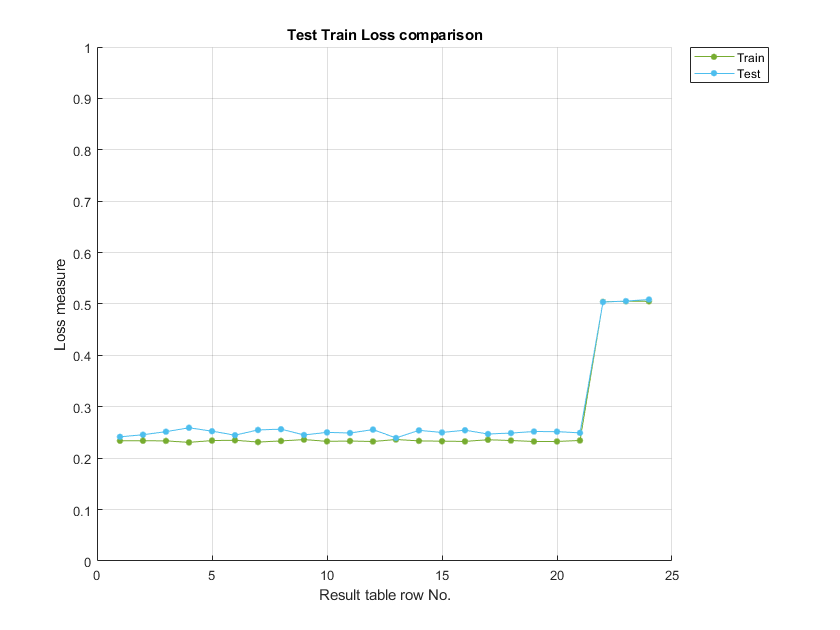

PlotUtil.plotLossTestTrainComparison(results.resultsTable, "Test Train Loss comparison");

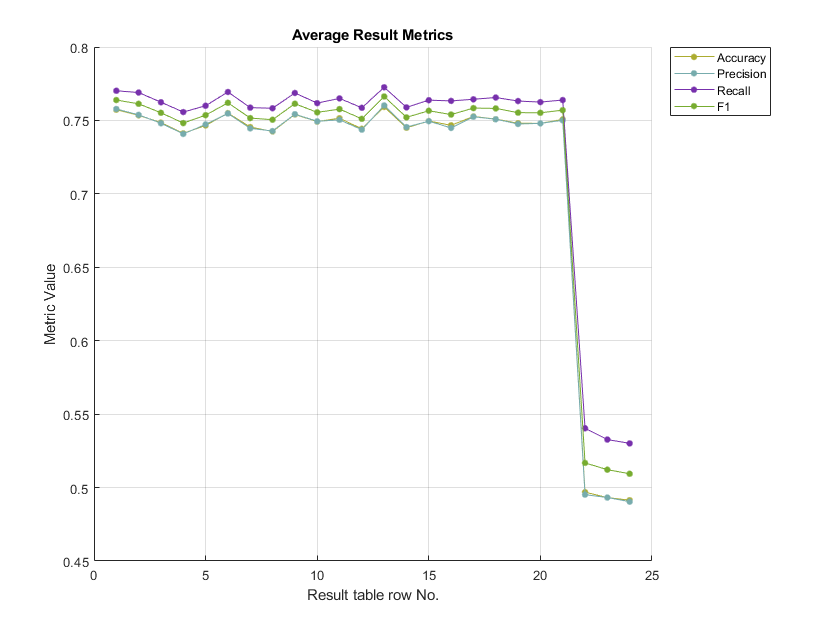

PlotUtil.plotMetrics(results.resultsTable, "Average Result Metrics");

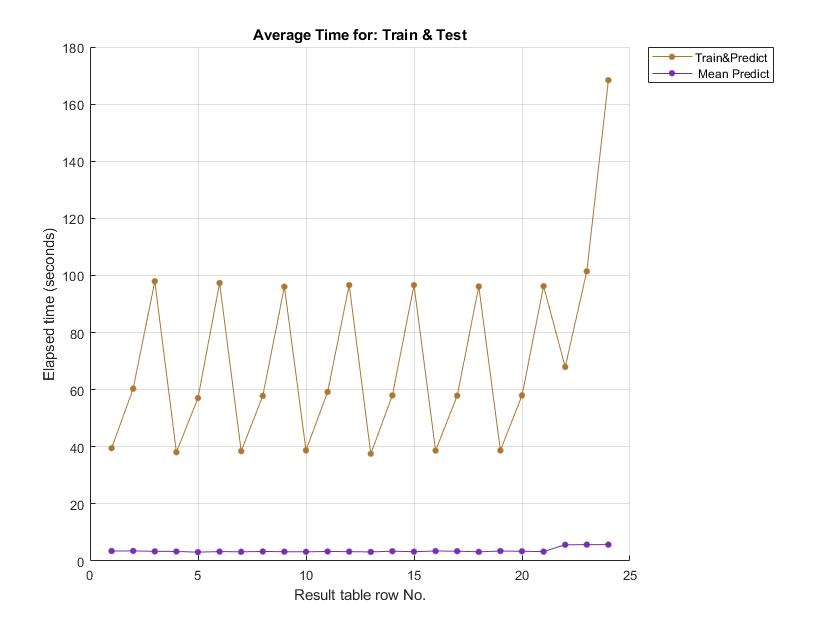

PlotUtil.plotTime(results.resultsTable, "Average Time for: Train & Test")

The rows that perform best in terms of accuracy are 1, 6, 9, 13, 18. 

disp(results.resultsTable([6, 9, 13, 18],:))

    distributionName    smootherType    Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ____________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}         {'box'}       0.18           5                  6              0.23

The hyperparameters to use here are:

**2 folds, normal kernel smoother, width 0.11**

bestBox = results.resultsTable([13],:)

bestBox = 1×14 table
    distributionName    smootherType    Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ____________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}         {'box'}       0.11           2                

### Final Hyperparameter Choice

bestTable = [bestTriangle(:,:); bestNormal(:,:); bestEpanechnikov(:,:); bestBox(:,:)];
disp(bestTable);

    distributionName      smootherType      Width    numberOfFolds    randomNBayesSeed    avgTrainLoss    avgTestLoss    avgAccuracy    avgPrecision    avgRecall    avgF1     entryCount    elapsedTime    avgPredictTime
    ________________    ________________    _____    _____________    ________________    ____________    ___________    ___________    ____________    _________    ______    __________    ___________    ______________

       {'kernel'}       {'triangle'    }    0.11           2                 13      

The best, in terms of test loss, is the normal smoother type with a width of 0.11, random seed 2. This is also the one that takes the longest:approximately 171 seconds to train and predict, 15 seconds to predict. 

The quickest is the box smoother type. Compared to the lowest loss, the difference in the metrics is very small (0.001).

All the smoother types have very similar and tightly groupd accuracy, precision, recall and F1.

The quickest model is chosen: **random seed 13, width 0.11, smoother type box, distribution name kernel.**

### Perform final test using optimal hyperparameters on complete dataset, save the model (manually)

#### Initialise

% CLear all, load the dataset
clear
clc
clf
close all
% loads the letter dataset 
% 
load letterDatasetClass.mat
letterDataset = letterDatasetNormalisedReducedFeatures;
disp(letterDataset);

  LetterDatasetClass with properties:

           datasetFilePath: "Dataset/letter-recognition.csv"
         testSetProportion: 0.200000000000000
                randomSeed: 1
                targetName: {'TargetAscii'}
              featureNames: {1×12 cell}
          validClassValues: [26×1 table]
    datasetContentsAsTable: [20000×13 table]
                trainTable: [16000×13 table]
                 testTable: [4000×13 table]
              isNormalised: 1
          isRemovedFeature: 1



#### Train

[xTrain, yTrain] = letterDataset.extractXYFromTable(letterDataset.trainTable);
classNames = categorical(table2array(letterDataset.validClassValues));
% distribution names used in the kernel distribution
distributionNames = {'kernel','kernel','kernel','kernel','kernel','kernel','kernel','kernel','kernel',...
  'kernel','kernel','kernel'};
distributionNames = distributionNames(:,:);
smootherTypes = { 'box', 'box', 'box', 'box', 'box', ...
  'box', 'box', 'box', 'box', 'box', 'box', 'box'};
    
[nBayesModel, trainTime] = NBayesClass.buildFinalNBayes(distributionNames, ...
        smootherTypes, 0.11, 13, classNames, xTrain, yTrain);

#### Test

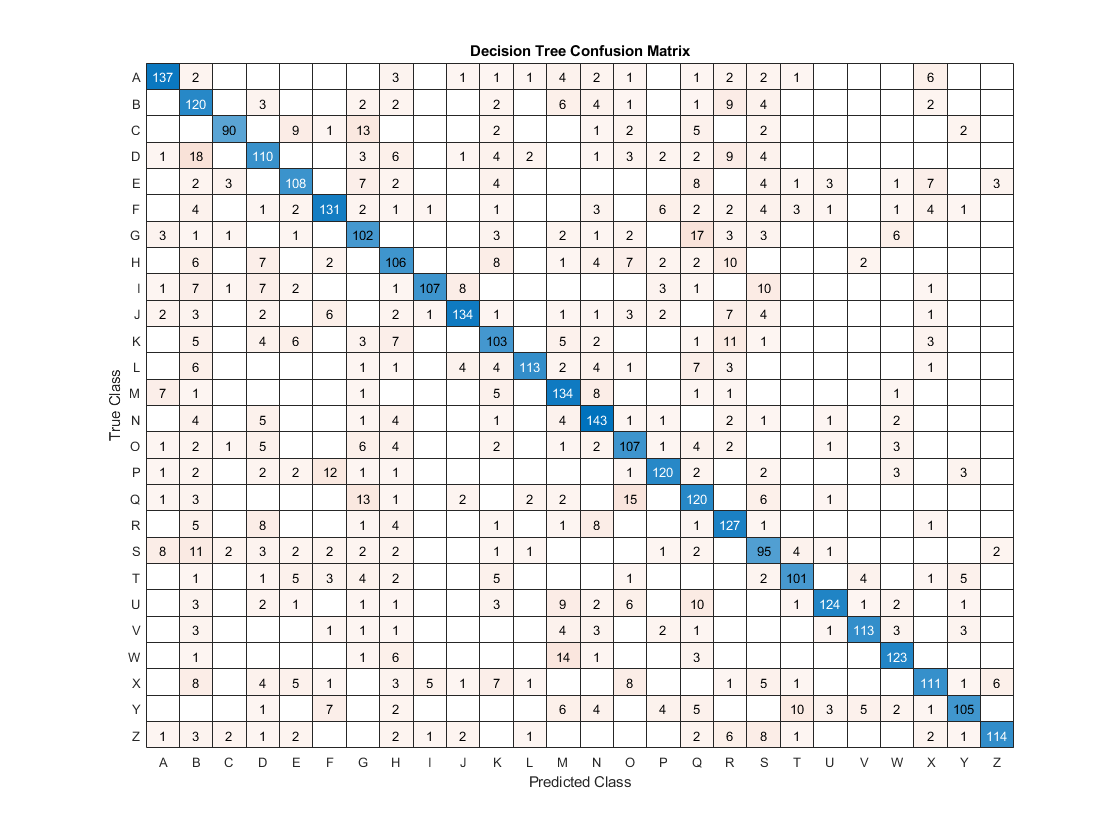

[xTest, yTest] = letterDataset.extractXYFromTable(letterDataset.testTable);
startTime = cputime;
[predictionResult, ~] = predict(nBayesModel, xTest(:,:));
predictTime = cputime - startTime;
% errors
misclassifiedCount = sum(predictionResult ~= categorical(table2array(yTest)));

[accuracy, precision, recall, ...
  f1] = CalcUtil.calculateMeasuresFromExpectPredict(table2array(yTest), predictionResult);

y = categorical(table2cell(yTest));
pred = categorical(predictionResult);
% Plot confusion matrix
PlotUtil.plotConfusionChart(y, pred, "Decision Tree Confusion Matrix");

fprintf("Accuracy: %0.04f Precision: %0.04f Recall: %0.04f F1 %0.04f. Train time: %0.04f Predict time: %0.04f\n", ...
  accuracy, precision, recall, f1, trainTime, predictTime);

Accuracy: 0.7495 Precision: 0.7491 Recall: 0.7675 F1 0.7582. Train time: 2.4688 Predict time: 8.2656


- The results' average test loss of 0.1186 is  very good. 

- The confusion matrix shows that the blue diagonal has a high proprtion of correct classifications. 

- The confusion matrix shows the misclassification of examples in light brown and correct classification in blue,.

### References

[1] [Multi-Class Metrics Made Simple, Part I: Precision and Recall | by Boaz Shmueli | Towards Data Science](https://towardsdatascience.com/multi-class-metrics-made-simple-part-i-precision-and-recall-9250280bddc2)

[2] [Multi-Class Metrics Made Simple, Part II: the F1-score | by Boaz Shmueli | Towards Data Science](https://towardsdatascience.com/multi-class-metrics-made-simple-part-ii-the-f1-score-ebe8b2c2ca1)

[3] Train multiclass naive Bayes model, fitcnb. MATLAB documentation. [https://www.mathworks.com/help/releases/R2020b/stats/fitcnb.html](https://www.mathworks.com/help/releases/R2020b/stats/fitcnb.html)

[4] T. G. Dietterich, “Approximate Statistical Tests for Comparing Supervised Classi cation Learning Algorithms,” p. 24.

[5] N. L. Pollesch and V. H. Dale, “Normalization in sustainability assessment: Methods and implications,” *Ecol. Econ.*, vol. 130, pp. 195–208, Oct. 2016, doi: 10.1016/j.ecolecon.2016.06.018.